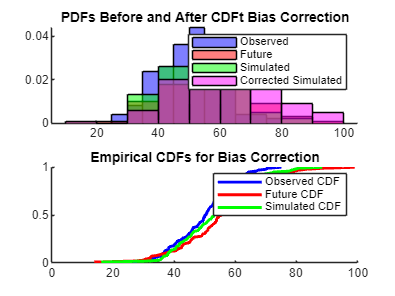

% CDFt Bias Correction in MATLAB (No Toolbox Required)
clc; clear; close all;

% Generate Dummy Time Series (Observed, Simulated)
n = ;  % Number of data points
observed = ;  % Observed Data (Reference)
simulated = ; % Simulated Data (To be Bias Corrected)
future = ;    % Future Projection (Target Distribution)

% Compute Empirical CDFs Manually
x_obs = sort(observed); 
cdf_obs = (1:n)' / n; % Observed CDF

x_sim = sort(simulated);
cdf_sim = (1:n)' / n; % Simulated CDF

x_fut = sort(future);
cdf_fut = (1:n)' / n; % Future CDF

% CDFt Bias Correction
corrected_simulated = zeros(size(simulated));
for i = 1:length(simulated)
    % Find closest CDF value in observed data
    [~, idx_obs] = min(abs(simulated(i) - x_obs));
    cdf_value = cdf_obs(idx_obs);
    
    % Find corresponding value in future data
    [~, idx_fut] = min(abs(cdf_fut - cdf_value));
    
    % Assign transformed value
    corrected_simulated(i) = x_fut(idx_fut);
end

% Plot Results
figure;
subplot(2,1,1);
hold on;
histogram(observed, 'Normalization', 'pdf', 'FaceColor', 'b', 'FaceAlpha', 0.5);
histogram(future, 'Normalization', 'pdf', 'FaceColor', 'r', 'FaceAlpha', 0.5);
histogram(simulated, 'Normalization', 'pdf', 'FaceColor', 'g', 'FaceAlpha', 0.5);
histogram(corrected_simulated, 'Normalization', 'pdf', 'FaceColor', 'm', 'FaceAlpha', 0.5);
legend('Observed', 'Future', 'Simulated', 'Corrected Simulated');
title('PDFs Before and After CDFt Bias Correction');
hold off;

subplot(2,1,2);
hold on;
plot(x_obs, cdf_obs, 'b', 'LineWidth', 2);
plot(x_fut, cdf_fut, 'r', 'LineWidth', 2);
plot(x_sim, cdf_sim, 'g', 'LineWidth', 2);
legend('Observed CDF', 'Future CDF', 'Simulated CDF');
title('Empirical CDFs for Bias Correction');
hold off;